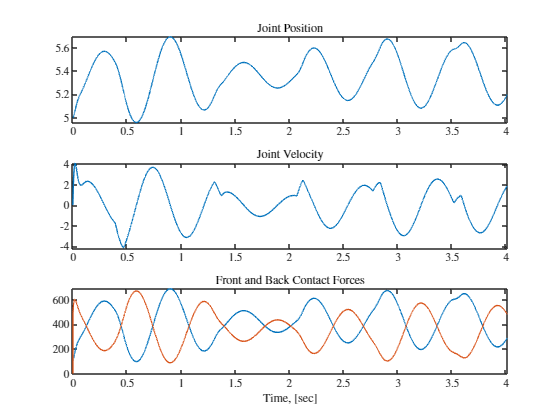

set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaulttextinterpreter','latex');

constraint_data = importdata("constraint_frc_data");
perturbation_data = importdata('perturbation_data');
joint_pos = importdata('joint_position_data');
joint_vel = importdata('joint_velocity_data');
contact_frc_data = importdata('contact_force_sensor');

% Sample data for plotting
x = constraint_data(:,1);
y1 = joint_pos(2:end,2);
y2 = joint_vel(:,2);
y3 = contact_frc_data(:,2);
y4= contact_frc_data(:,3);
% y3 = constraint_data(:,2);
% y4 = constraint_data(:,3);

% Create a new figure
figure;

% Draw vertical lines
lineX = [3, 6, 8]; % x-values where vertical lines should be drawn
lineY = [min(y4), max(y4)]; % y-limits for the vertical lines

% Subplot 1
subplot(3, 1, 1);
plot(x(2:end), y1);
title('Joint Position');
% set(gca, 'xtick', []); % Turn off x-axis ticks
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], [min(y1), max(y1)], 'Color', 'b', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
axis([min(x), max(x), min(y1), max(y1)]);

% Subplot 2
subplot(3, 1, 2);
plot(x, y2);
title('Joint Velocity');
% set(gca, 'xtick', []); % Turn off x-axis ticks
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], [min(y2), max(y2)], 'Color', 'k', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
axis([min(x), max(x), min(y2), max(y2)]);

% Subplot 3
subplot(3, 1, 3);
plot(x, y3);
hold on;
plot(x,y4);
title('Front and Back Contact Forces');
% set(gca, 'title', []); % Turn off x-axis ticks
% set(gca, 'xtick', []); % Turn off x-axis ticks
xlabel('Time, t [sec]')
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], [min(y3), max(y3)], 'Color', 'k', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
axis([min(x), max(x), min(y3), max(y3)]);

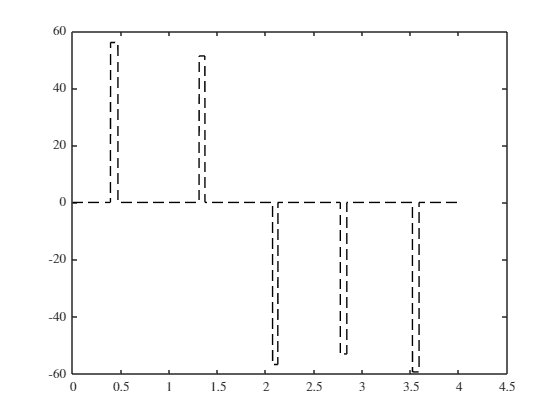


% % Subplot 4
% subplot(4, 1, 4);
% plot(x, -1*y4);
% title('Subplot 4: constraint4');
% xlabel('x'); % Label the x-axis for the bottom subplot
% hold on;
% for i = 1:length(lineX)
%     line([lineX(i), lineX(i)], lineY, 'Color', 'k', 'LineStyle', '--'); % Draw each vertical line
% end
% hold off;
% axis([min(x), max(x), min(y4), max(y4)]);

% % Adjusting subplot spacing
% spacing = 0.05;
% position = get(gca, 'Position');
% position(3) = position(3) + spacing*3;
% position(2) = position(2) + spacing;
% position(4) = position(4) - spacing * 2;
% set(gca, 'Position', position);

figure;
plot(perturbation_data(:,1), perturbation_data(:,2),'Color', 'k', 'LineStyle', '--');